N=1000;
f=linspace(0.0001,5.0001e9,N);
Mag=zeros(1,N);
Phase=zeros(1,N);
omega=2*pi*f;
mu=4*pi*1e-7;
eps=8.85*1e-12;
Z1=1i*omega*mu;
Y1=1i*(omega*eps-kc^2./omega/mu);
Z0=sqrt(Z1./Y1);
a=60*1e-3;
kc=2*pi/2/a;
loop=1;
for omega_=2*pi*f
    Th=[1 1i*omega_*mu/2/Z0(loop);
        0 1];
    Tv=[1 0;
        Z0(loop)/(1i*omega_*mu/kc^2)+1i*omega_*eps 1];
    T=Th*Tv*Th;
    S21=2/(T(1,1)+T(1,2)+T(2,1)+T(2,2));
    Mag(loop)=abs(S21);
    Phase(loop)=angle(S21);
    loop=loop+1;
end


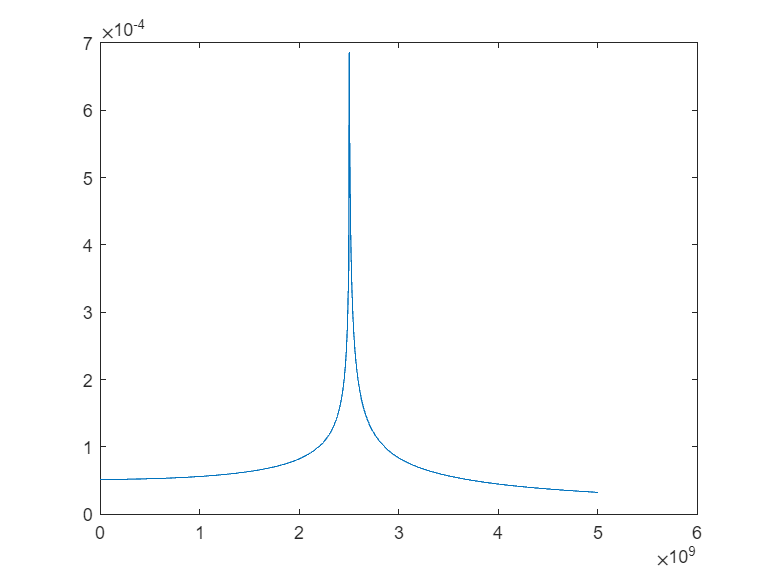

hi=figure;
plot(f,Mag)

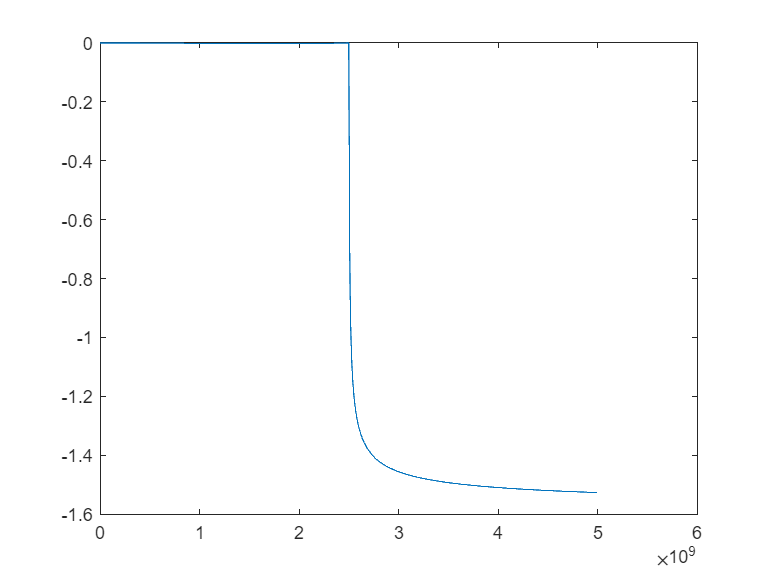

h2=figure;
plot(f,Phase)